# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `layers` 中创建层。

要了解详细信息，请参阅 [从 Deep Network Designer 生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2021-02-22 11:01:06 自动生成

## 创建层组

layers = [
    featureInputLayer(7,"Name","featureinput")
    fullyConnectedLayer(20,"Name","fc_1")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(20,"Name","fc_2")
    reluLayer("Name","relu_2")
    fullyConnectedLayer(20,"Name","fc_3")
    fullyConnectedLayer(1,"Name","fc_4")
    regressionLayer("Name","regressionoutput")];

## 绘制层

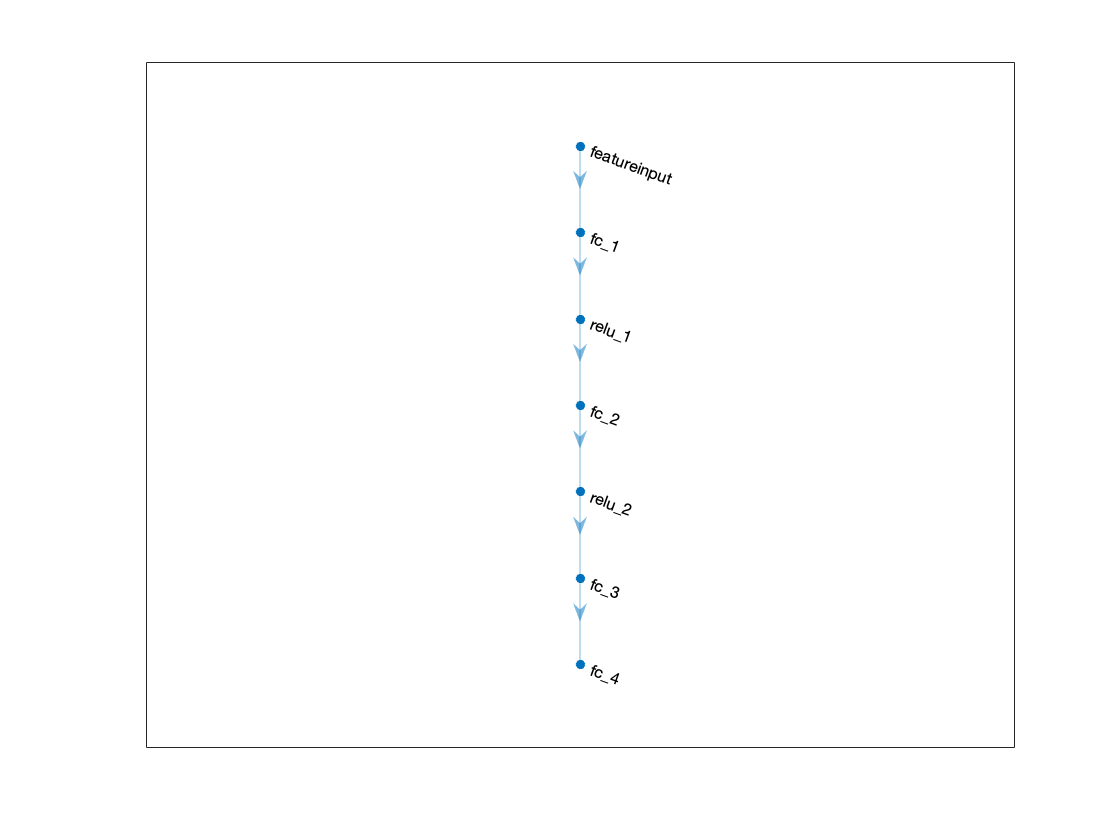

plot(layerGraph(layers));

table_trim_data = readtable('trim_redundant_data_generation_2_22_night.csv');
table_trim_data = table_trim_data(~isnan(table_trim_data{:,end}),:);

trim_predictor = table_trim_data{:,1:7};
trim_response = table_trim_data{:,end};

miniBatchSize = 16;

options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false);

net = trainNetwork(trim_predictor,trim_response,layers,options) 

net =   SeriesNetwork - 属性:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'featureinput'}
    OutputNames: {'regressionoutput'}
